# MATLAB Basics

### [1] Overview on programming  languages

**MATLAB **, which is programming language intended primarily for numeric computing, is a proprietary software

**GNU Octave,** which is mostly compatible with MATLAB, is a free software

**R**, which is a programming language for statistical computing, is a free software

**Julia, **which a programming language suited for numerical analysis and scientific computing, is a free software

**Python**, which is [general-purpose programming language](https://en.wikipedia.org/wiki/General-purpose_programming_language), is a free software

These five platforms are [high-level](https://en.wikipedia.org/wiki/High-level_programming_language), [dynamic](https://en.wikipedia.org/wiki/Dynamic_programming_language) [programming language](https://en.wikipedia.org/wiki/Programming_language)s that are used for scientific and engineering applications

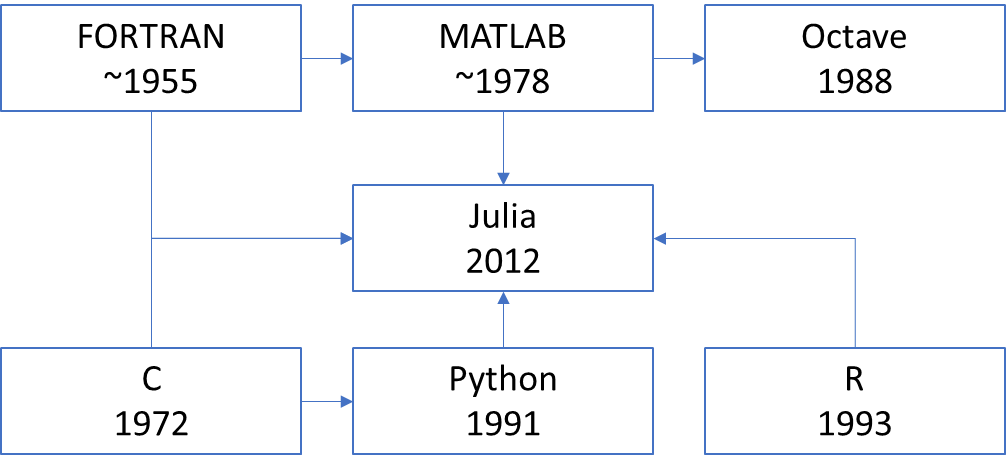

*Fig.1 Timeline of programming language showing predecessor(s)*

### **[2] Workspace basics**

clear %clear all variables in the workspace
A=1 %Defining a variable A number    

A = 1

a="Welcome to MATLAB" %Defining a variable a srtring and suppresses output (;)

a = "Welcome to MATLAB"

disp(A)%display number (print to screen)

     1



disp(a)%display string (print to screen)

Welcome to MATLAB


disp(a + "  "+ num2str(A) + " and you can write anything")%display string + number 

Welcome to MATLAB  1 and you can write anything


%format (use pi as an example)
format long
al=pi

al =    3.141592653589793


format default
as=pi

as = 3.1416

### **[3] Scalar and array variables**

A=1%scaler

A = 1

A1=[3 5 7 1]%row vector

A1 =      3     5     7     1


A2=[3;5;7;1]%column vector

A2 =      3
     5
     7
     1


A3=[3 5 7 1]'%Prime symbol transpose an array

A3 =      3
     5
     7
     1


A4=[1 2 3 4;50 60 70 80;2 1 4 5]%matrix

A4 =      1     2     3     4
    50    60    70    80
     2     1     4     5



A5="Hi"%String scalar

A5 = "Hi"

A6=["Hi" "Hello" "Welcome"]%String array

A6 = 1×3 string array
    "Hi"    "Hello"    "Welcome"


Variable name (identifier)

- case sensitivecan

- can be sequence of letters (a-z, A-Z), digits (0-9), or underscores (_), 

- must start with a letter

- Cannot be a MATLAB keyword

- Avoid using a function name (e.g., log, sin, sum, etc.) as a good practice

MATLAB keyword: break, case,   catch,classdef,  continue, else,  elseif, end, for, function, global, if, otherwise, parfor, persistent, return, spmd, switch, try, while 

%"for" keyword will give an error because it is a MATLAB keywork
for n=1:3
    n+1
end

ans = 2

ans = 3

ans = 4


%Try to us a MATLAB built-in function name (bad programming practice)
sum=5

sum = 5

S=[10 20 30]

S =     10    20    30


S1=sum(S)

Index exceeds the number of array elements. Index must not exceed 1.

'sum' appears to be both a function and a variable. If this is unintentional, use 'clear sum' to remove the variable 'sum' from the workspace.

%You need to clear the sum variable from memory to solve this problem
clear
S=[10 20 30]

S =     10    20    30


S1=sum(S)

S1 = 60

### **[4] Arthemtic operators**

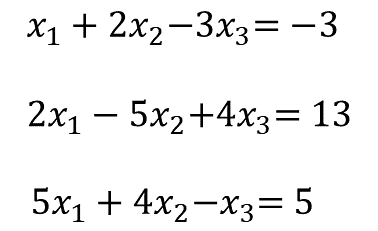

% +/-: Addition and subtraction
A1=3

A1 = 3

A2=5

A2 = 5

A3=[3 4 5]

A3 =      3     4     5


A4=[30 40 50]

A4 =     30    40    50


A5=A3+A4

A5 =     33    44    55



%Array 
% .*: Element wise multiplication  
A6=A3.*A4

A6 =     90   160   250



% *: Matrix multiplication 
A7=A3*A4'

A7 = 500


% Elementwise division
A6=A3./A4

A6 =     0.1000    0.1000    0.1000



% Matrix division 
% /: Rigth division Solve xA= B for x [i.e., A/B= A x inv(B)]
% \: Left division  Solve Ax= B for x [i.e,  A\B= inv(A) x B]
A=[1 2 -3;2 -5 4;5 4 -1]

A =      1     2    -3
     2    -5     4
     5     4    -1


B=[-3; 13; 5]

B =     -3
    13
     5


x=A\B

x =     2.0000
   -1.0000
    1.0000


% .^: Element wise power/nth root (A.^n)
% ^: Matrix power/nth root (A^n)
A=[4 3; 2 2]

A =      4     3
     2     2


A1=A.^2

A1 =     16     9
     4     4


A2=A^2

A2 =     22    18
    12    10


**Exercise 1**

Calculate z where ${z=\left(x^3 -y^2 \right)}^{2/5}$  where  x=5.1 and y=$-0\ldotp 4$

Answer: z=7.0611

x=5.1

x = 5.1000

y=-0.4

y = -0.4000

z=(x^3-y^2)^(2/5)

z = 7.0611

**Exercise 2**

Heat transport 

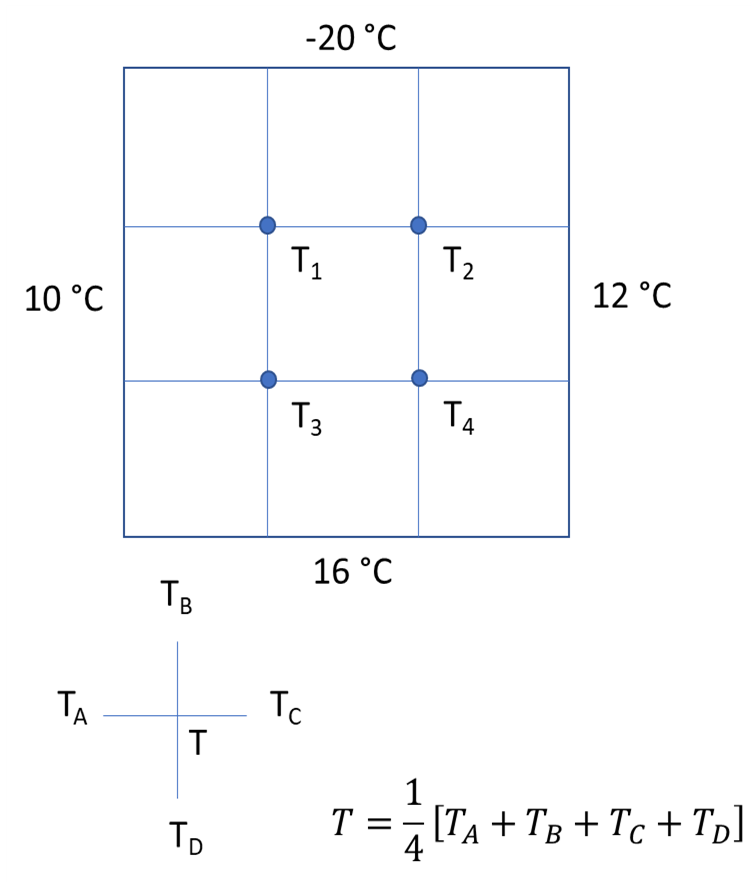


$$4T_1 -T_2 -T_3 +0=-10$$



$$-T_1 +4T_2 +{0-\;T}_4 =-8$$



$$-T_1 +0+{4T}_3 -T_4 =26$$



$$0-T_2 -T_3 +4T_{4\;} =28$$



$$\begin{array}{l}
\textrm{Ax}=B\\
x=A^{-1\;} \times \;B
\end{array}$$


Write down Matrix A (4$\left.\times 4\right)$and B ( 4$\left.\times 1\right)$ and solve for z

Remember: 

- / Rigth division Solve xA= B for x [i.e., $A/B=A\times B^{-1}$] 

- \ Left division  Solve Ax= B for x [i.e,  $A\backslash B=A^{-1} \times B$]

Answer: -0.25, 0.25, 8.75, and 9.25

A=[4 -1 -1 0;-1 4 0 -1;-1 0 4 -1;0 -1 -1 4]

A =      4    -1    -1     0
    -1     4     0    -1
    -1     0     4    -1
     0    -1    -1     4


B=[-10;-8;26;28]

B =    -10
    -8
    26
    28


x=A\B

x =    -0.2500
    0.2500
    8.7500
    9.2500


Try solving the same problem using $x=A^{-1} \times B$. Hint: Use the function `inv(A) `for$A^{-1}$ 

x=inv(A)*B

x =    -0.2500
    0.2500
    8.7500
    9.2500


### **[5] Elementary functions**

% (4.1) Common math functions
x=-1000

x = -1000

x1=sign(x) % sign() give the sign of x               

x1 = -1

x2=abs(x)% abs() compute absolute value |x|

x2 = 1000

x3=sqrt(x2)% sqrt() compute square root of x

x3 = 31.6228

x4=log(x2)% log(x) compute ln(x)

x4 = 6.9078

x5=log10(x2)% log10(x) compute log_10(x)

x5 = 3

x6=exp(x4)% exp() compute exponential e^x (e is the Euler's number)

x6 = 1.0000e+03

% (4.2) Trignometric functions (sin, cos, tan,cot, ...)
A=30;  %Degree
A1=deg2rad(A)% deg2rad(): Convert angle from degree to radians

A1 = 0.5236

A2=rad2deg(A1) % rad2deg(): Convert angle from radians to degree

A2 = 30.0000


A3=sin(A1)% sin(): Sine of argument in radians 

A3 = 0.5000

A4=sind(A2)% sind(): Sine of argument in degrees 

A4 = 0.5000

A5=asin(A3)% asin(): Inverse sine in radians sin^-1(A)

A5 = 0.5236

A6=asind(A3)% asind(): Inverse sine in degrees sin^-1(A)

A6 = 30.0000

A7=sinh(A1)% sinh(): Hyberbolic sine (function defined using the hyperbola rather than the circle)

A7 = 0.5479

% (4.3) Discrete math function
d=455.68458788856

d = 455.6846

d1=round(d) % round(x): rounds each element of X to the nearest integer

d1 = 456

d2=round(d,0)% round(x,N): N = 0: round to the nearest integer.

d2 = 456

d3=round(d,2)% round(x,N): N > 0: round to N digits to the right of the decimal point

d3 = 455.6800

d4=round(d,-1)% round(x,N): N < 0: round to N digits to the left of the decimal point

d4 = 460

d5=round(d,-2)% round(x,N): N < 0: round to N digits to the left of the decimal point

d5 = 500

% (4.4) Descriptive Statistics
C=[50 40 40 60 80 100 90 40]

C =     50    40    40    60    80   100    90    40


ca=bounds(C) %bounds(A) Smallest and largest elements

ca = 40

[CA, CB]=bounds(C) %bounds(A) Smallest and largest elements

CA = 40

CB = 100


C1=max(C)      %max(A) Maximum elements of an array

C1 = 100

C2=min(C)      %min(A) Minimum elements of an array

C2 = 40

C3=mode(C)     %mode(A) Most frequent values in array

C3 = 40

C4=mean(C)     %mean(A) Average or mean value of array

C4 = 62.5000

C5=median(C)   %median(A) Median value of array

C5 = 55

C6=std(C)      %std(A) Standard deviation

C6 = 24.3487

C7=var(C)      %var(A) Variance

C7 = 592.8571

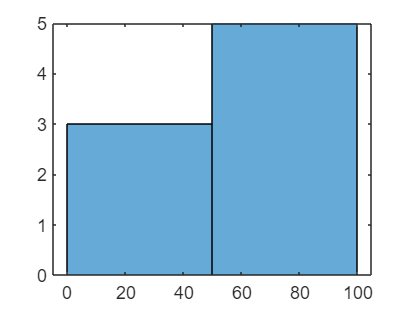

histogram(C)   %histogram(A) calculate and plot histogram

### **[6] Constants **

pi % pi: Number pi π (ratio of circle's circumference to its diameter ≈ 3.14159265)

ans = 3.1416


Con=inf % inf: Infinity 

Con = Inf

inf+inf

ans = Inf

inf/inf

ans = NaN

% NaN: Not-a-number

realmin % realmin: Smallest positive floating-point number

ans = 2.2251e-308

realmax % realmax: Largest positive floating-point number

ans = 1.7977e+308

eps % eps: Machine precision that is the floating point relative accuracy

ans = 2.2204e-16


% eps: Machine epsilon also known as machine precision and unit round-of,
% which is the distance between a floating point and its nearest neighbor.
% Numbers that differs by less than the machine epsilon are numerically the same
% esp+1 > 1. Try: 1+0.5*eps==1
% Note floating-point arithmetic is arithmetic that represents real numbers
% approximately (https://en.wikipedia.org/wiki/Floating-point_arithmetic)

### **[7] Precedence rules**

( ) , ^ Power, - unary minus (used to show a negative number), * / , + -, left-to-right

15 + (12+ 11) + 5*4/5

15 +     23    + 5*4/5

15 +     23    + 20/5

15 +     23    + 4

    38           + 4

                 42

Is the expression `2*3^3`  equivalent to ${\left(2\times 3\right)}^3$ or  $2\times 3^3$?

If in doubts, use parentheses instead of relying on your knowledge of precedence rules.

2*(3^3)

ans = 54

n=3

n = 3

m=5*-n

m = -15

**Execrcise 3**

Calculate z where ${z=\left(x^3 +y^2 \right)}^{2/5} +\frac{x^2 y\pi \;}{2\left(\sin \left(y\right)-\log \left(x\right)\right)}$  where  x=5.1 and y=${-0\ldotp 4}^{\circ }$

Answer: z=29.9390

%Calculate z
x=5.1;
y=-0.4;
z=(x^3+y^2)^(2/5)+x^2*y*pi/(2*(sind(y)-log10(x)))

%If in doubt, do it one-by-one and use parentheses
A=((x^3)+(y^2))^(2/5);
B=(x^2)*y*pi;
C=2*(sind(y)-log10(x));
zc=A+B/C

### **[8] An engineering problem: Groundwater flow**

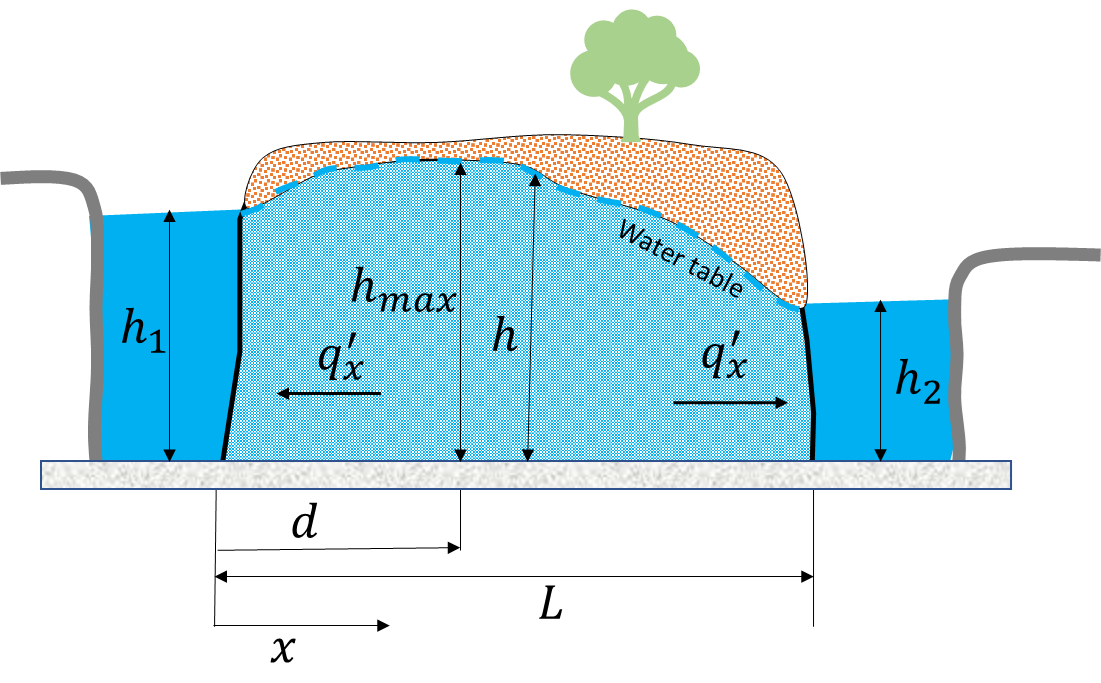

A canal was constructed running parallel to a river $L$ = 2000 m away. Both fully penetrate a sand aquifer with a hydraulic conductivity of $K$= 1.5 m/d. The area is subject to recharge of $\omega =$0.0017 m/d. The elevation of the water in the river is $h_{1\;}$=30 m and in the canal it is $h_2 =$20 m. The width into river and canal is W=600 m. Determine:

(1)  water divide $d$ (m)


$$d=\frac{L}{2\;}-\frac{K}{\omega \;}\frac{\left(h_1^2 -h_2^2 \right)}{2L}$$


(2) Maximum water-table elevation $h_{\max \;}$(m)


$$h_{\max \;} =\sqrt{h_1^2 -\frac{\left(h_1^2 -h_2^2 \right)d}{L}+\frac{\omega }{K}\left(L-d\right)d\;}$$


(3) Daily discharge $q_{x\;}$($m^3 /d$) into the river (i.e., x=0)

(4) Daily discharge $q_{x\;}$($m^3 /d$) into the canal (i.e, x=L)


$$q_{x\;} =\left\lbrack \frac{K\left(h_1^2 -h_2^2 \right)}{2L}-\omega \;\left(\frac{L}{2}-x\right)\right\rbrack \times W$$


Display your answers in two significant figures with annotation using `disp()` function

Answers: d=890; hmax=42; qx_river=-910; qx_canal=1100

**Solution**

%Input 
L=2000;  %Distance from river to canal (m) 
K=1.5;  %  Hydraulic conductivity (m/d)
w=0.0017; %recharge (m/d)
h1=30;  %water elevation in river (m)
h2=20;  % water elevation in canal  (m)
W=600; %depth into river or canal(m)

% Water divide d (m from river)
d=(L/2)-(K/w)*(h1^2-h2^2)/(2*L);
d=round(d,-1); 
disp("The water-table divide is " + num2str(d) + " m from the river")

%Maximum water-table elevation hmax (m)
hmax=sqrt(h1^2-(h1^2-h2^2)*d/L+(w/K)*(L-d)*d);
hmax=round(hmax,0);

The water-table divide is 890 m from the river


disp("The maximum water-table elevation is " + num2str(hmax) + " m")

%Daily discharge (m^3/d) into the river(i.e., x=0)
x=0;
qx_river=(K*(h1^2-h2^2)/(2*L)-w*((L/2)-x))*W;

The maximum water-table elevation is 42 m


qx_river=round(qx_river,-1);  
disp("Daily discharge (m^3/d) into the river is " + num2str(qx_river) + " m^3/d")


%Daily discharge (m^3/d) into the canal (i.e, x=L)
x=L;

Daily discharge (m^3/d) into the river is -910 m^3/d


qx_canal=(K*(h1^2-h2^2)/(2*L)-w*((L/2)-x))*W;
qx_canal=round(qx_canal,-2);
disp("Daily discharge (m^3/d) into the canal is " + num2str(qx_canal) + " m^3/d")

### **Extra practice at home 1**

This is an extra execrcise in case you want to do more practice at home

Show that A=B=8


$${A=\left({{\textrm{csc30}}^{\circ \;} \textrm{tan45}}^{\circ } {\textrm{cot45}}^{\circ } +{\textrm{sec0}}^{\circ \;} \right)}^3 +\frac{\sin^2 {30}^{\circ \;} }{\cos^2 {60}^{\circ \;} }$$


$B=\frac{a^5 -2a-2}{a^2 -1}-\frac{e^{2t} }{e^a }$ where t=0.5 and ${a=\textrm{tan45}}^{\circ } +{\textrm{sin90}}^{\circ }$

%Sove for A

%Solve for B

**Solution**

%Sove for A

Daily discharge (m^3/d) into the canal is 1100 m^3/d


A=(cscd(30)*tand(45)*cotd(45)+secd(0))^2-sind(30)^2/cosd(60)^2
t=0.5;

%Sove for B
a=tand(45)+sind(90);
B=(a^5-2*a-1)/(a^2-1)-exp(4*t)/exp(a)

%Extra (logical operator that give 1 if true and zero if false) 
%We will to logical opertors next week
Check1=A==B

### **Extra practice at home 2**

This is an extra execrcise in case you want to do more practice at home 

Problem is modified from Chapra and Canale (1998)

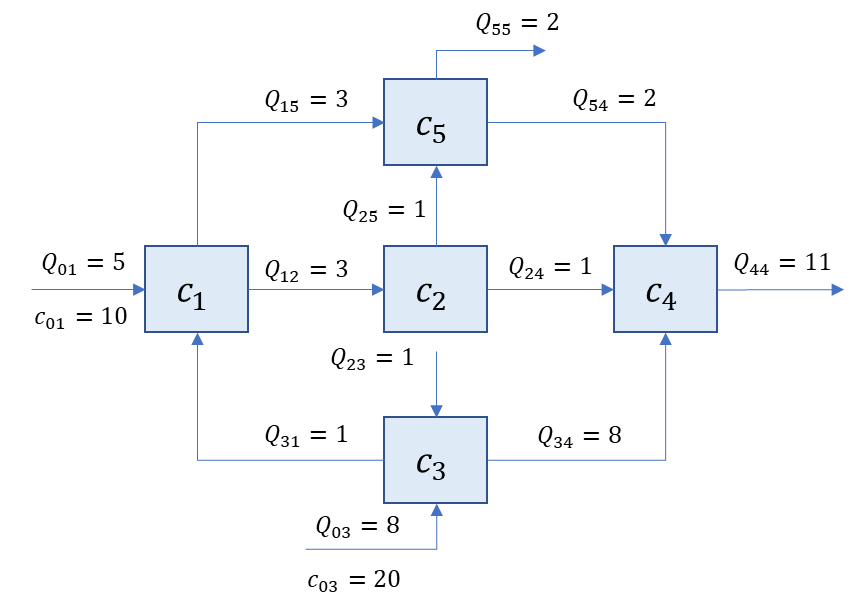

We can do mass balance by taken the flow rate Q ($\left.m^3 /\min \right)$ and the concentration of nutrient c ($\textrm{mg}/m^3$) to get the rate at which mass flows (mg/min). The system is in a steady state that means the mass flow in is equal to mass flow out. The mass balance of a lake system (of five connected lakes) as shown above, can thus be expresses as


$$\begin{array}{l}
6c_1 -c_3 =50\\
-3c_1 +3c_2 =0\\
-c_2 +9c_3 =160\\
-c_2 -8c_3 +11c_4 -2c_5 =0\\
-3c_1 -c_2 +4c_5 =0
\end{array}$$


For exampe for lake 1, input mass flow rate  = output mass flow rate that is $5\left(10\right)+Q_{31} \left(c_3 \right)=Q_{15} \left(c_1 \right)+Q_{12} \left(c_1 \right)$, which will give the first equation. You can do the same for the other lakes to get the above system of linear equations. 

Now, if the concentration $c_i$ for lake $i$ is above the water quality concentration threshold  $c_{\textrm{threshold}}$of 18 $\textrm{mg}/m^3$, then the lake is not safe for recreational activities.  Display a text on the screen that shows that lakes that are not safe for recreational activities.

%Solution steps
%(1) Solve system of linear equation for ci (c1, c2, c3, c4, c5)

A = 8


%(2) Use disp function to show your assessment

**Solution**

%Solution steps
%(1) Solve system of linear equation for c
A=[6 0 -1 0 0;-3 3 0 0 0;0 -1 9 0 0;0 -1 -8 11 -2;-3 -1 0 0 4]

B = 8

B=[50; 0; 160; 0; 0]
c=A\B  %Left division to Solve Ax= B for x

%(2) Use disp to show your assessment

Check1 = logical
   1


disp("Given the nutrient concentrations of ")
disp(num2str(c'))
disp("for the five lakes, respectively,")
disp("lake 3 is not safe for for recreational activities")

%Extra (logical operator that give 1 if true and zero if false) 
%We will do logical opertors next week
c_threshold=18;
Check=c>=c_threshold

A =      6     0    -1     0     0
    -3     3     0     0     0
     0    -1     9     0     0
     0    -1    -8    11    -2
    -3    -1     0     0     4


B =     50
     0
   160
     0
     0


c =    11.5094
   11.5094
   19.0566
   16.9983
   11.5094


Given the nutrient concentrations of 


11.5094      11.5094      19.0566      16.9983      11.5094


for the five lakes, respectively,


lake 3 is not safe for for recreational activities


Check = 5×1 logical array
   0
   0
   1
   0
   0
